Boas práticas :)


clear;
close all;
clc;

Lendo e organizando os dados do modelo SIR

data = readtable("S:/Users/20.01521-6/Desktop/Sistemas-Controle-main/SIRpd.csv")

data = 1000×3 table
      S         I          R    
    ______    ______    ________

       499         1           0
    498.95    1.0407    0.010213
     498.9    1.0831    0.020841
    498.84    1.1273    0.031903
    498.78    1.1732    0.043415
    498.72     1.221    0.055396
    498.66    1.2707    0.067865
     498.6    1.3224    0.080842
    498.53    1.3762    0.094347
    498.46    1.4322      0.1084
    498.39    1.4905     0.12303
    498.31    1.5511     0.13825
    498.23    1.6142     0.15409
    498.15    1.6799     0.17057
    498.06    1.7482     0.18773
    497.98    1.8192     0.20558


data = table2array(data);

dias = 1:length(data);

 Criando ruído para os dados e os adicionando

Sd = data(1:end,1);
Id = data(1:end,2);
Rd = data(1:end,3);

Sdn = wgn(1000,1,0);
Idn = wgn(1000,1,0);
Rdn = wgn(1000,1,0);

Sd = Sd + Sdn;
Id = Id + Idn;
Rd = Rd + Rdn;  

Visualizando os dados

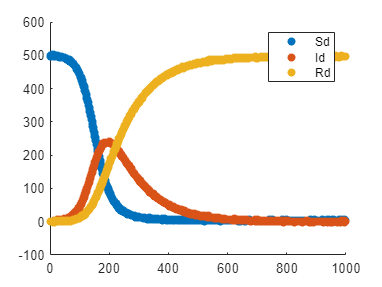

figure(1)

scatter(dias, Sd,'filled')
hold on
scatter(dias, Id,'filled')
hold on
scatter(dias, Rd,'filled')

legend("Sd", "Id", "Rd")

Obtendo valores iniciais

%Tamanho da populção - N
N = 500;

%Valores iniciais 
I0 = 1;
R0 = 0;
S0 = N - I0;

y0 = [S0 I0 R0];

theta0 = [1e-4 1e-2];
Beta = 1e-4;

Beta = 1.0000e-04

r = 1e-2;

r = 0.0100

Utilizando o simulador do modelo SIR

simOut = sim("modelo_covid_aula1.slx")

simOut =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [1004x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Analisando o resultado da simulação

St = simOut.logsout{1}.Values.Data;

St =   499.0000
  498.9990
  498.9940
  498.9685
  498.9163
  498.8620
  498.8055
  498.7467
  498.6856
  498.6219


It = simOut.logsout{2}.Values.Data;

It =     1.0000
    1.0008
    1.0048
    1.0252
    1.0669
    1.1103
    1.1555
    1.2025
    1.2514
    1.3023


Rt = simOut.logsout{3}.Values.Data;

Rt =          0
    0.0002
    0.0012
    0.0063
    0.0168
    0.0277
    0.0390
    0.0508
    0.0630
    0.0758



t = 1:length(St);

t =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


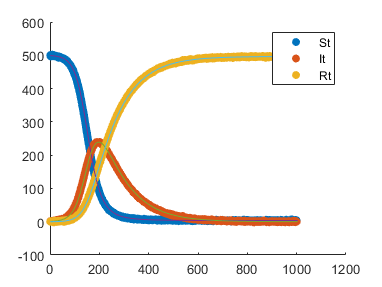

%Plot dados SIR
figure(1)

scatter(dias, Sd,'filled')
hold on
scatter(dias, Id,'filled')
hold on
scatter(dias, Rd,'filled')

legend("Sd", "Id", "Rd")

%Plot dados simulador

plot(t, St)
hold on
plot(t, It)
hold on
plot(t, Rt)

legend("St", "It", "Rt")

Otimizando Beta e r

function [Ss, Is, Rs] = simulator(S0, I0, R0, theta0)
    % inicializa o simulador SimuLink e retorna os valores previstos
    % para cada variável de saída (S, I e R)
    Beta = theta0(1)
    r = theta0(2)

    % ativando a simulação
    simOut = sim("modelo_covid_aula1.slx")
    Ss = simOut.logsout{1}.Values.Data;
    Is = simOut.logsout{2}.Values.Data;
    Rs = simOut.logsout{3}.Values.Data;
end
